# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

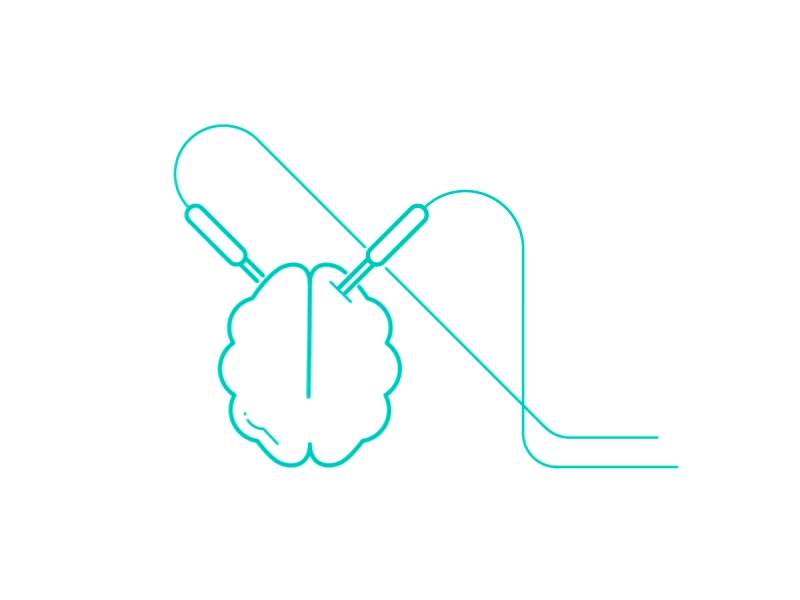

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = []; % Clear Deci Parameters
Deci.Folder.Raw         = ['C:\Users\User\Desktop\NE329\Module1\RawData']; % Location of the "RawData" Folder
Deci.SubjectList = 'gui'; % Manually Select which subject to analyze
Deci.Step               = 5; % Which step to do.
Deci.PCom = false;
     %Step 1: Trial Definition
          %Reads through the vmrk file and  indentify trials of interest.
     %Step 2: Preprocessing
          % Implicit Rereferencing of online and offline electroes
          % Bandpass filter out frequencies not of interest
          % ICA matrix computation
Deci.Folder.Version     = ['C:\Users\User\Desktop\NE329\Module1\ProcessedData'];
Deci.Retroactive  = true;

## 1. Trial Definitions

Deci.DT.Type       = 'LCM';
Deci.DT.Starts     = {192};         %Cell Array of Markers for Trial Start.
Deci.DT.Ends       = {193};         %Cell Array of Markers for Trial End.
Deci.DT.Markers    = {[10 11]  [100:102] [199:200] };
%                       L/R       H        RCor
Deci.DT.Locks      = [9 99 198];
%                     S1 S2 R
Deci.DT.Toi        = [-2 3];
% Cell Array of Markers for Block Starts

## 2. PreProcessing Steps

Deci.PP = [];
%Deci.PP.filter.bpfreq = [1 30];
%Deci.PP.filter.bpfilter = 'yes';

Deci.PP.ShowData = false;
Deci.ICA.do = true;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.Manual_Trial_Rejection = true;
Deci.Art.ShowArt = true;
Deci.Art.More.channel = {'TP10' 'TP9' 'PO7' 'PO8' 'TVEOG' 'BVEOG' 'RHEOG' 'LHEOG'};

## 4. Analysis

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;

%N2PC

Analysis = 'N2PC';

switch Analysis
    case 'N2PC'
        Deci.Analysis.Channels = {'PO7' 'PO8'};
        Deci.Analysis.Locks         = [2];                                                          % Which Lock to Analyze
        Deci.Analysis.LocksTitle    = {'Stimulus 2 Onset'};                      % Folder Title to save each Lock as
        Deci.Plot.BslRef = 'Stimulus 2 Onset';
        Deci.Plot.Lock =   'Stimulus 2 Onset';
        Deci.Analysis.Conditions    = {[101 102]};
        
        Deci.Analysis.HemifieldFlip.do = true;
        Deci.Analysis.HemifieldFlip.Markers = [101 102];
        
        Deci.Analysis.CondTitle     = {'Search Array Onset'};
        Deci.Analysis.Version = [Deci.Folder.Version];
        Deci.Plot.Wire.Channel =  [{'PO7' 'PO8'}];              % Channel of Interest
        Deci.Plot.Bsl     = [-.2 0];
    case 'CDA'
        Deci.Analysis.Channels = {'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8'};
        Deci.Analysis.Locks         = [1];                                                          % Which Lock to Analyze
        Deci.Analysis.LocksTitle    = {'Stimulus 1 Onset'};                      % Folder Title to save each Lock as
        Deci.Plot.BslRef = 'Stimulus 1 Onset'
        Deci.Plot.Lock =   'Stimulus 1 Onset';
        Deci.Analysis.Conditions    = {[10 11]};
       
        Deci.Analysis.HemifieldFlip.do = true;
        Deci.Analysis.HemifieldFlip.Markers = [10 11];
        
        Deci.Analysis.CondTitle     = {'Cue Onset'};
        Deci.Analysis.Version = [Deci.Folder.Version];
        Deci.Plot.Wire.Channel =  {'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8'}; 
        %Deci.Plot.Wire.Channel =  {'PO4' 'O2' 'PO8' 'P8'}; 
        %Deci.Plot.Wire.Channel =  {'PO3' 'O1' 'PO7' 'P7'}; 
        
        Deci.Plot.Bsl     = [-.2 0];
end

Deci.Analysis.Toilim = [-2 3];
Deci.Analysis.Toi = [-.5 1.5];

Deci.Analysis.ERP.do  = true;

if Deci.Step == 4
    Deci.DT.Markers    = {[10 11]  [100:102] [199:200]};
    
    %Analysistypes = {'Exp_Analysis1', 'Exp_Analysis2'};
    %    for AnalysisLocks = Analysistypes
    %       eval(AnalysisLocks{1})
    Deci_Backend(Deci);
    %   end
end

## 5. Plotting

Deci.Plot.Version = [Deci.Analysis.Version];
Deci.Plot.Figures      = [true];
Deci.Plot.Math         = {};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1]};                   % Cell array of Condition Index for each figure

Deci.Plot.Title        = {'All Trials'};          % Title for each figure
Deci.Plot.Subtitle     = {{'Onset'}};     % Cell array of strings of subtitles for each Condition

%Deci.Run.Freq =false;
Deci.Run.ERP =true;
Deci.Run.Extra = false;


Deci.Plot.ERP.PP.bpfreq = [.1 30];
Deci.Plot.ERP.PP.bpfilter = 'yes';
Deci.Plot.ERP.PP.detrend   = 'yes';

Deci.Plot.GrandAverage = true;

Deci.Plot.Hemiflip.do = true;
Deci.Plot.Hemiflip.Type = 'Both';

Deci.Plot.Topo.do    =false;
Deci.Plot.Topo.Toi     =[.2 .4];                   % Time of Interest
Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.Wire.do    =false;
Deci.Plot.Wire.Channel =  [{'PO7' 'PO8'}];            % Channel of Interest
Deci.Plot.Wire.Toi     = [0 .5];                   % Time of Interest

Deci.Plot.Bar.do    =true;
Deci.Plot.Bar.Toi     = [.2 .4];                    % Time of Interest
Deci.Plot.Bar.Channel =  [{'PO7' 'PO8'}];            % Channel of Interest

Deci.Plot.Stat.do = false; % Will only work if for large subject pools
if Deci.Plot.Stat.do
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.alpha = .05;
    Deci.Plot.Stat.correctm = 'no';
end

if Deci.Step ~= 4
    
    Deci_Backend(Deci);
end

Deci is running retroactive subjects


ans = logical
   1


Running Deci for 1 subjects
 
----------------------
 
Plotting ERP
Loading Plottor for Subject #1: Module1_03
preprocessing
preprocessing trial 597 from 597

the call to "ft_preprocessing" took 1 seconds
preprocessing
preprocessing trial 597 from 597

the call to "ft_preprocessing" took 1 seconds
